# Figures of average acoustic features per bat

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
GGPath = dir('/Users/elie/Google Drive*');
Path2Paper = fullfile(GGPath.folder, GGPath.name, 'My Drive', 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicAudioGood','CallType','OnSetOffsetSample',...
    'TmicAll7','BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','F0_cv','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean', 'AmpPeriodF','AmpPeriodP')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
MicAudioGoodInd = find(MicAudioGood01);
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;
fprintf(1,'In total, there are %d Vocal elements, %d are also of good microphone quality\n', length(MicAudioGood01), sum(MicAudioGood01))

In total, there are 36227 Vocal elements, 28091 are also of good microphone quality


Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Female';
    end

end
USexDeaf = {'Kanamycin Male' 'Saline Male' 'Kanamycin Female' 'Saline Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

Construct the table of PAF for statistical purposes

Tbl =  table(BatID(MicAudioGoodInd(TmicAll7==5)),...
    CallType(MicAudioGoodInd(TmicAll7==5)),...
    Sex(MicAudioGoodInd(TmicAll7==5)),...
    Deaf(MicAudioGoodInd(TmicAll7==5)),...
    DurationElmt(MicAudioGoodInd(TmicAll7==5)),...
    RMS_mean(MicAudioGoodInd(TmicAll7==5)),...
    Sal_mean(MicAudioGoodInd(TmicAll7==5)),...
    F0_mean(MicAudioGoodInd(TmicAll7==5))/1000,...
    F0_cv(MicAudioGoodInd(TmicAll7==5)),...
    Spect_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    Spect_std(MicAudioGoodInd(TmicAll7==5))/10^3,...
    Spect_kurt(MicAudioGoodInd(TmicAll7==5)),...
    Spect_skew(MicAudioGoodInd(TmicAll7==5)),...
    Spect_ent(MicAudioGoodInd(TmicAll7==5)),...
    Time_mean(MicAudioGoodInd(TmicAll7==5)),...
    Time_std(MicAudioGoodInd(TmicAll7==5)),...
    Time_kurt(MicAudioGoodInd(TmicAll7==5)),...
    Time_skew(MicAudioGoodInd(TmicAll7==5)),...
    Time_ent(MicAudioGoodInd(TmicAll7==5)),...
    Q1_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    Q2_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    Q3_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    SpectMic_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    SpectMic_std(MicAudioGoodInd(TmicAll7==5))/10^3,...
    SpectMic_kurt(MicAudioGoodInd(TmicAll7==5)),...
    SpectMic_skew(MicAudioGoodInd(TmicAll7==5)),...
    SpectMic_ent(MicAudioGoodInd(TmicAll7==5)),...
    Q1Mic_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    Q2Mic_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    Q3Mic_mean(MicAudioGoodInd(TmicAll7==5))/10^3,...
    AmpPeriodF(MicAudioGoodInd(TmicAll7==5)),...
    AmpPeriodP(MicAudioGoodInd(TmicAll7==5)),...
    'VariableNames', {'BatID', 'CT','Sex','HorD',...
    'Duration (ms)','RMS mean','Saliency (AU)','F0 (kHz)','F0 CV','Spectral mean (kHz)','Spectral std (kHz)','Spectral kurtosis (Hz)','Spectral skewness (Hz)','Spectral entropy',...
    'Time mean (ms)','Time std (ms)','Time kurtosis (ms)','Time skewness (ms)','Time entropy','First quartile (kHz)','Second quartile (kHz)','Third quartile (kHz)','Mic Spectral mean (kHz)','Mic Spectral std (kHz)',...
    'Mic Spectral kurtosis (Hz)','Mic Spectral skewness (Hz)','Mic Spectral entropy','Mic First quartile (kHz)','Mic Second quartile (kHz)','Mic Third quartile (kHz)','Amplitude Periodicity F (Hz)','Amplitude Periodicity P'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});

Go through all acoustic categories and calculate and plot the average values of features for all individuals

% List of variables
AcVars = Tbl.Properties.VariableNames(5:end);
Pvalue_matrix_Post_hoc = nan(length(AcVars),1);
BatMales = BatName(contains(BatSexDeaf, 'Male'));
BatSexDeafMales = BatSexDeaf(contains(BatSexDeaf, 'Male'));
Fig1=figure(1);
clf
T=tiledlayout(4,7,'TileSpacing','compact');
set(gcf,'Visible','on')
INN = contains(Tbl.Sex, 'M');
for vv=1:length(AcVars)
    fprintf(1, '*********************     Calculations on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    Tbl_local = table(Tbl.BatID(INN), Tbl.CT(INN), Tbl.HorD(INN), AcVar(INN), 'VariableNames', {'BatID', 'CT','HorD', 'AcVar'});
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ 1 + (1|BatID)');
    TestLME_HD=compare(lmeR, lme)
    Pvalue_matrix_Post_hoc(vv) = TestLME_HD.pValue(2);

    lme

    % Nice plot 1
    AcVar_mean_pBat = nan(size(BatMales));
    AcVar_se_pBat = nan(size(BatMales));
    Col_local = nan(length(BatMales),3);
    for bb=1:length(BatMales)
        Ind = INN(strcmp(Tbl.BatID(INN),num2str(BatMales(bb))));
        
        AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
        AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeafMales{bb}),:);
    end

   
    AcVarMean_HD = [mean(AcVar_mean_pBat(contains(BatSexDeafMales, 'Kanamycin'))) mean(AcVar_mean_pBat(contains(BatSexDeafMales, 'Saline')))];
    AcVarSE_HD = [std(AcVar_mean_pBat(contains(BatSexDeafMales, 'Kanamycin')))/sum(contains(BatSexDeafMales, 'Kanamycin'))^0.5 std(AcVar_mean_pBat(contains(BatSexDeafMales, 'Saline')))/sum(contains(BatSexDeafMales, 'Saline'))^0.5];
    
    N=nexttile(vv,[1,1]);
    XHorD = [0.5 1.5 2.5 3.5];
%     XHorD(contains(BatSexDeafMales, 'Saline')) = XHorD(contains(BatSexDeafMales, 'Saline'))+2;
    errorbar([1 3],AcVarMean_HD, 2*AcVarSE_HD, 2*AcVarSE_HD, 'k.','LineWidth',2)
    hold on
    B=bar([1 3], AcVarMean_HD);
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.','LineWidth',2)
    hold on
    scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
    ylabel(sprintf('%s', AcVars{vv}), 'FontSize',12)
    XLim = [0 4];
    set(gca, 'XLim', XLim);
    YLim = get(gca, 'YLim');
    MinVal = min(AcVar_mean_pBat-2*AcVar_se_pBat);
    MaxVal = max(AcVar_mean_pBat+2*AcVar_se_pBat);
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
%     YLim(1) = MinVal - (MaxVal-MinVal)*2/3;
    set(gca, 'YLim', YLim)
%     if vv==length(AcVars)
%         for ct=1:length(USexDeaf(1:2))
%             text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
%         end
%     end
    if vv>21
        set(gca, 'XTick', [1 3],'XTickLabel', {'Kanamycin' 'Saline'}, 'FontSize',12)
    else
        set(gca, 'XTick', [1 3],'XTickLabel', {'' ''})
    end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)], 'FontSize',10)
    hold off
    if ~(TestLME_HD.pValue(2) <0.01)
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
%         T.FontWeight = 'normal';
%         T.Color = 0.7.*ones(1,3);
    else
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        hold on
        plot([1 3], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
        text(2,(19/20*diff(YLim) + YLim(1)), '<.01','FontSize', 9)
    end
    N.Box = 0;
    

    %         nexttile
    %         errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
    %         hold on
    %         scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
    %         ylabel(sprintf('%s (z-scored)', AcVars{vv}))
    %         XLim = [0 4];
    %         set(gca, 'XLim', XLim);
    %         YLim = get(gca, 'YLim');
    %         for ct=1:length(USexDeaf)
    %             text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
    %         end
    %         set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
    %         hold off
    %         title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))


end

*********************     Calculations on Duration (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lmeR     3     40285    40303    -20139                                  
    lme      4     40278    40302    -20135    8.9063    1          0.0028418


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    40278    40302    -20135           40270   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        123.72      17.503    7.0686    3067    1.9295e-12    89.401    158.04
    {'HorD_D'     }        143.31      25.429    5.6357    3067    1.9019e-08    93.448    193.17

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     Upper 

*********************     Calculations on RMS mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     3     -5282.1    -5264.1    2644.1                                 
    lme      4     -5280.3    -5256.2    2644.2    0.19466    1          0.65906


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -5280.3    -5256.2    2644.2           -5288.3 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue        Lower        Upper   
    {'(Intercept)'}           0.2751    0.014734      18.67    3067    9.1198e-74      0.24621     0.30399
    {'HorD_D'     }        0.0094656    0.021132    0.44792    3067       0.65424    -0.031969    0.050901

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type    

*********************     Calculations on Saliency (AU)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue
    lmeR     3     -3177.6    -3159.5    1591.8                                
    lme      4     -3165.4    -3141.3    1586.7    -10.187    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3067
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -3165.4    -3141.3    1586.7           -3173.4 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}         0.76814    0.0030056    255.57    3065             0     0.76225     0.77404
    {'HorD_D'     }        0.038142    0.0060221    6.3336    3065    2.7446e-10    0.026334    0.049949

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type          

*********************     Calculations on F0 (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue
    lmeR     3       3815    3832.6    -1904.5                                
    lme      4     3816.8    3840.4    -1904.4    0.11875    1          0.7304


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2672
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3816.8    3840.4    -1904.4          3808.8  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat       DF      pValue        Lower       Upper  
    {'(Intercept)'}          1.6569    0.10981      15.089    2670    1.9613e-49      1.4416     1.8723
    {'HorD_D'     }        -0.05414    0.15621    -0.34659    2670       0.72893    -0.36044    0.25216

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on F0 CV   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -2315.2    -2297.6    1160.6                                  
    lme      4     -2321.4    -2297.9    1164.7    8.1695    1          0.0042601


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            2672
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2321.4    -2297.9    1164.7           -2329.4 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}         0.05997    0.011486    5.2212    2670    1.9142e-07    0.037448    0.082492
    {'HorD_D'     }        0.086462    0.017046    5.0724    2670    4.1976e-07    0.053038     0.11989

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Es

*********************     Calculations on Spectral mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat      deltaDF    pValue 
    lmeR     3     520.43    538.52    -257.22                                  
    lme      4     522.33    546.45    -257.17    0.099272    1          0.75271


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    522.33    546.45    -257.17          514.33  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue         Lower       Upper  
    {'(Intercept)'}             2.2    0.079754     27.585    3067    8.1902e-150      2.0436     2.3564
    {'HorD_D'     }        0.035909     0.11316    0.31733    3067        0.75101    -0.18597    0.25778

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on Spectral std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     3     888.19    906.28     -441.1                                 
    lme      4     889.79    913.91    -440.89    0.40138    1          0.52637


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    889.79    913.91    -440.89          881.79  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue        Lower      Upper   
    {'(Intercept)'}         0.77553    0.047001       16.5    3067    1.1455e-58    0.68337     0.86768
    {'HorD_D'     }        -0.04361    0.067164    -0.6493    3067       0.51619    -0.1753    0.088081

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on Spectral kurtosis (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lmeR     3     33025    33043    -16510                                
    lme      4     33031    33055    -16512    -4.2009    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    33031    33055    -16512           33023   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue         Lower     Upper 
    {'(Intercept)'}        35.441      1.0939    32.398    3067    2.7104e-198    33.296    37.586
    {'HorD_D'     }        7.9426      2.1925    3.6225    3067     0.00029645    3.6436    12.242

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower    Uppe

*********************     Calculations on Spectral skewness (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat     deltaDF    pValue
    lmeR     3     14530    14548    -7261.8                                
    lme      4     14539    14563    -7265.7    -7.6323    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14539    14563    -7265.7          14531   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower      Upper  
    {'(Intercept)'}          3.834     0.053776    71.294    3067             0     3.7285     3.9394
    {'HorD_D'     }        0.69175      0.10778    6.4181    3067    1.5931e-10    0.48042    0.90308

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lowe

*********************     Calculations on Spectral entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue
    lmeR     3     -5200.9    -5182.8    2603.4                                
    lme      4     -5196.4    -5172.2    2602.2    -2.5371    1          1     


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -5196.4    -5172.2    2602.2           -5204.4 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF      pValue        Lower        Upper     
    {'(Intercept)'}          0.53369    0.0021587     247.23    3067             0      0.52945       0.53792
    {'HorD_D'     }        -0.017854    0.0043266    -4.1265    3067    3.7806e-05    -0.026337    -0.0093705

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                 

*********************     Calculations on Time mean (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -6397.4    -6379.3    3201.7                                  
    lme      4     -6405.7    -6381.6    3206.9    10.273    1          0.0013497


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6405.7    -6381.6    3206.9           -6413.7 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower       Upper   
    {'(Intercept)'}         0.05894    0.0080193    7.3498    3067    2.5324e-13    0.043217    0.074664
    {'HorD_D'     }        0.079294     0.011703    6.7755    3067    1.4802e-11    0.056347     0.10224

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type          

*********************     Calculations on Time std (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -10090    -10072    5048.2                                  
    lme      4     -10097    -10073    5052.4    8.3708    1          0.0038129


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -10097    -10073    5052.4           -10105  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue        Lower      Upper   
    {'(Intercept)'}        0.029567    0.0047675    6.2019    3067    6.3275e-10    0.02022    0.038915
    {'HorD_D'     }        0.036221    0.0069268    5.2291    3067    1.8172e-07    0.02264    0.049803

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on Time kurtosis (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     3     4548.2    4566.3    -2271.1                                 
    lme      4       4547    4571.1    -2269.5    3.2212    1          0.072691


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    4547    4571.1    -2269.5          4539    

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue      Lower         Upper  
    {'(Intercept)'}          2.1036    0.010558    199.24    3067           0        2.0829     2.1243
    {'HorD_D'     }        0.037989    0.021161    1.7952    3067    0.072715    -0.0035022    0.07948

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate     

*********************     Calculations on Time skewness (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue   
    lmeR     3     861.26    879.35    -427.63                                  
    lme      4     853.19    877.31     -422.6    10.064    1          0.0015122


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    853.19    877.31    -422.6           845.19  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF      pValue        Lower       Upper   
    {'(Intercept)'}         0.11886    0.025322     4.6941    3067    2.7958e-06    0.069214     0.16851
    {'HorD_D'     }        -0.24854    0.037027    -6.7126    3067    2.2688e-11    -0.32114    -0.17595

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Est

*********************     Calculations on Time entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue  
    lmeR     3     -14619    -14600    7312.3                                 
    lme      4     -14620    -14596      7314    3.5459    1          0.059693


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -14620    -14596    7314             -14628  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF      pValue      Lower        Upper   
    {'(Intercept)'}        0.95868     0.0032222    297.52    3067           0      0.95236       0.965
    {'HorD_D'     }        0.01098     0.0046212     2.376    3067    0.017565    0.0019188    0.020041

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on First quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat      deltaDF    pValue 
    lmeR     3     -1849.3    -1831.2    927.67                                  
    lme      4     -1847.4    -1823.3     927.7    0.063486    1          0.80107


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -1847.4    -1823.3    927.7            -1855.4 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue     Lower        Upper  
    {'(Intercept)'}          1.9789      0.0392    50.483    3067          0       1.9021     2.0558
    {'HorD_D'     }        0.014135    0.055781    0.2534    3067    0.79998    -0.095238    0.12351

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate   

*********************     Calculations on Second quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lmeR     3     2979.2    2997.3    -1486.6                                 
    lme      4     2978.4    3002.5    -1485.2    2.8318    1          0.092414


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2978.4    3002.5    -1485.2          2970.4  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue      Lower       Upper      
    {'(Intercept)'}           3.5306    0.030072      117.4    3067           0      3.4716         3.5895
    {'HorD_D'     }        -0.087381    0.044522    -1.9626    3067    0.049779    -0.17468    -8.4445e-05

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type        

*********************     Calculations on Third quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     3     6284.1    6302.2      -3139                                
    lme      4     6285.1    6309.2    -3138.5    1.0081    1          0.31535


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    6285.1    6309.2    -3138.5          6277.1  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue     Lower        Upper   
    {'(Intercept)'}           5.8726    0.014014     419.05    3067          0       5.8451      5.9001
    {'HorD_D'     }        -0.028204    0.028088    -1.0041    3067    0.31539    -0.083276    0.026869

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estima

*********************     Calculations on Mic Spectral mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     12747    12765    -6370.7                                  
    lme      4     12740    12764    -6366.2    8.9461    1          0.0027806


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12740    12764    -6366.2          12732   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        3.1861      0.29971    10.631    3067    6.0322e-26    2.5985    3.7737
    {'HorD_D'     }        2.5067      0.42901    5.8429    3067    5.6686e-09    1.6655    3.3479

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower      Up

*********************     Calculations on Mic Spectral std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     12122    12140      -6058                                  
    lme      4     12115    12139    -6053.3    9.3709    1          0.0022046


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12115    12139    -6053.3          12107   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        3.2112      0.21356    15.037    3067    2.3151e-49    2.7925      3.63
    {'HorD_D'     }        1.9422      0.30784     6.309    3067    3.2128e-10    1.3386    2.5457

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     Upp

*********************     Calculations on Mic Spectral kurtosis (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     3     42210    42228    -21102                                 
    lme      4     42207    42231    -21099    5.0902    1          0.024062


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    42207    42231    -21099           42199   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE       tStat      DF      pValue        Lower      Upper  
    {'(Intercept)'}         143.13     18.66     7.6706    3067    2.2839e-14     106.54     179.72
    {'HorD_D'     }        -93.136     27.54    -3.3819    3067    0.00072898    -147.13    -39.137

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     

*********************     Calculations on Mic Spectral skewness (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue  
    lmeR     3     19858    19876    -9926.1                                 
    lme      4     19854    19878    -9923.1    5.8947    1          0.015187


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    19854    19878    -9923.1          19846   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue        Lower      Upper 
    {'(Intercept)'}         7.6683     0.75124     10.208    3067    4.4329e-24     6.1953    9.1413
    {'HorD_D'     }        -4.0365       1.083    -3.7271    3067    0.00019721    -6.1601    -1.913

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower  

*********************     Calculations on Mic Spectral entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue   
    lmeR     3     -4149.8    -4131.7    2077.9                                  
    lme      4     -4156.6    -4132.5    2082.3    8.7716    1          0.0030596


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -4156.6    -4132.5    2082.3           -4164.6 

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue         Lower      Upper  
    {'(Intercept)'}        0.41209     0.018584    22.174    3067    3.6451e-101    0.37565    0.44852
    {'HorD_D'     }        0.15082      0.02662    5.6658    3067     1.5988e-08    0.09863    0.20302

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estim

*********************     Calculations on Mic First quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     12420    12438    -6207.1                                  
    lme      4     12415    12439    -6203.4    7.5383    1          0.0060402


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    12415    12439    -6203.4          12407   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        5.1288      0.29305    17.502    3067    1.9026e-65    4.5542    5.7034
    {'HorD_D'     }        2.0161      0.41919    4.8096    3067    1.5854e-06    1.1942     2.838

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower      Up

*********************     Calculations on Mic Second quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     15765    15784    -7879.7                                  
    lme      4     15760    15784    -7875.8    7.8727    1          0.0050188


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    15760    15784    -7875.8          15752   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue         Lower     Upper 
    {'(Intercept)'}        11.227      0.36823    30.488    3067    1.4907e-178    10.505    11.949
    {'HorD_D'     }        2.7065      0.53179    5.0893    3067     3.8104e-07    1.6638    3.7492

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     

*********************     Calculations on Mic Third quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik     LRStat    deltaDF    pValue   
    lmeR     3     18920    18938    -9456.9                                  
    lme      4     18912    18936    -9452.2    9.4542    1          0.0021067


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    18912    18936    -9452.2          18904   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF      pValue        Lower     Upper 
    {'(Intercept)'}        19.686      0.10965    179.54    3067             0    19.471    19.901
    {'HorD_D'     }        3.2142      0.21976    14.626    3067    7.0189e-47    2.7833    3.6451

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower    Uppe

*********************     Calculations on Amplitude Periodicity F (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    lmeR     3     33988    34006    -16991                                 
    lme      4     33983    34008    -16988    6.085     1          0.013633


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    33983    34008    -16988           33975   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF      pValue        Lower      Upper 
    {'(Intercept)'}          94.91     9.3088    10.196    3067    4.9863e-24     76.658    113.16
    {'HorD_D'     }        -50.173     13.333    -3.763    3067    0.00017102    -76.315    -24.03

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type           Estimate    Lower     Upp

*********************     Calculations on Amplitude Periodicity P   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue    
    lmeR     3     -12146    -12128    6076.2                                   
    lme      4     -12156    -12132      6082    11.624    1          0.00065115


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3069
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                2

Formula:
    AcVar ~ 1 + HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -12156    -12132    6082             -12164  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE            tStat     DF      pValue        Lower        Upper    
    {'(Intercept)'}        0.0056264    0.00069465    8.0997    3067    7.8708e-16    0.0042644    0.0069884
    {'HorD_D'     }        0.0047512     0.0013922    3.4126    3067    0.00065182    0.0020213     0.007481

Random effects covariance parameters (95% CIs):
Group: BatID (4 Levels)
    Name1                  Name2                  Type  

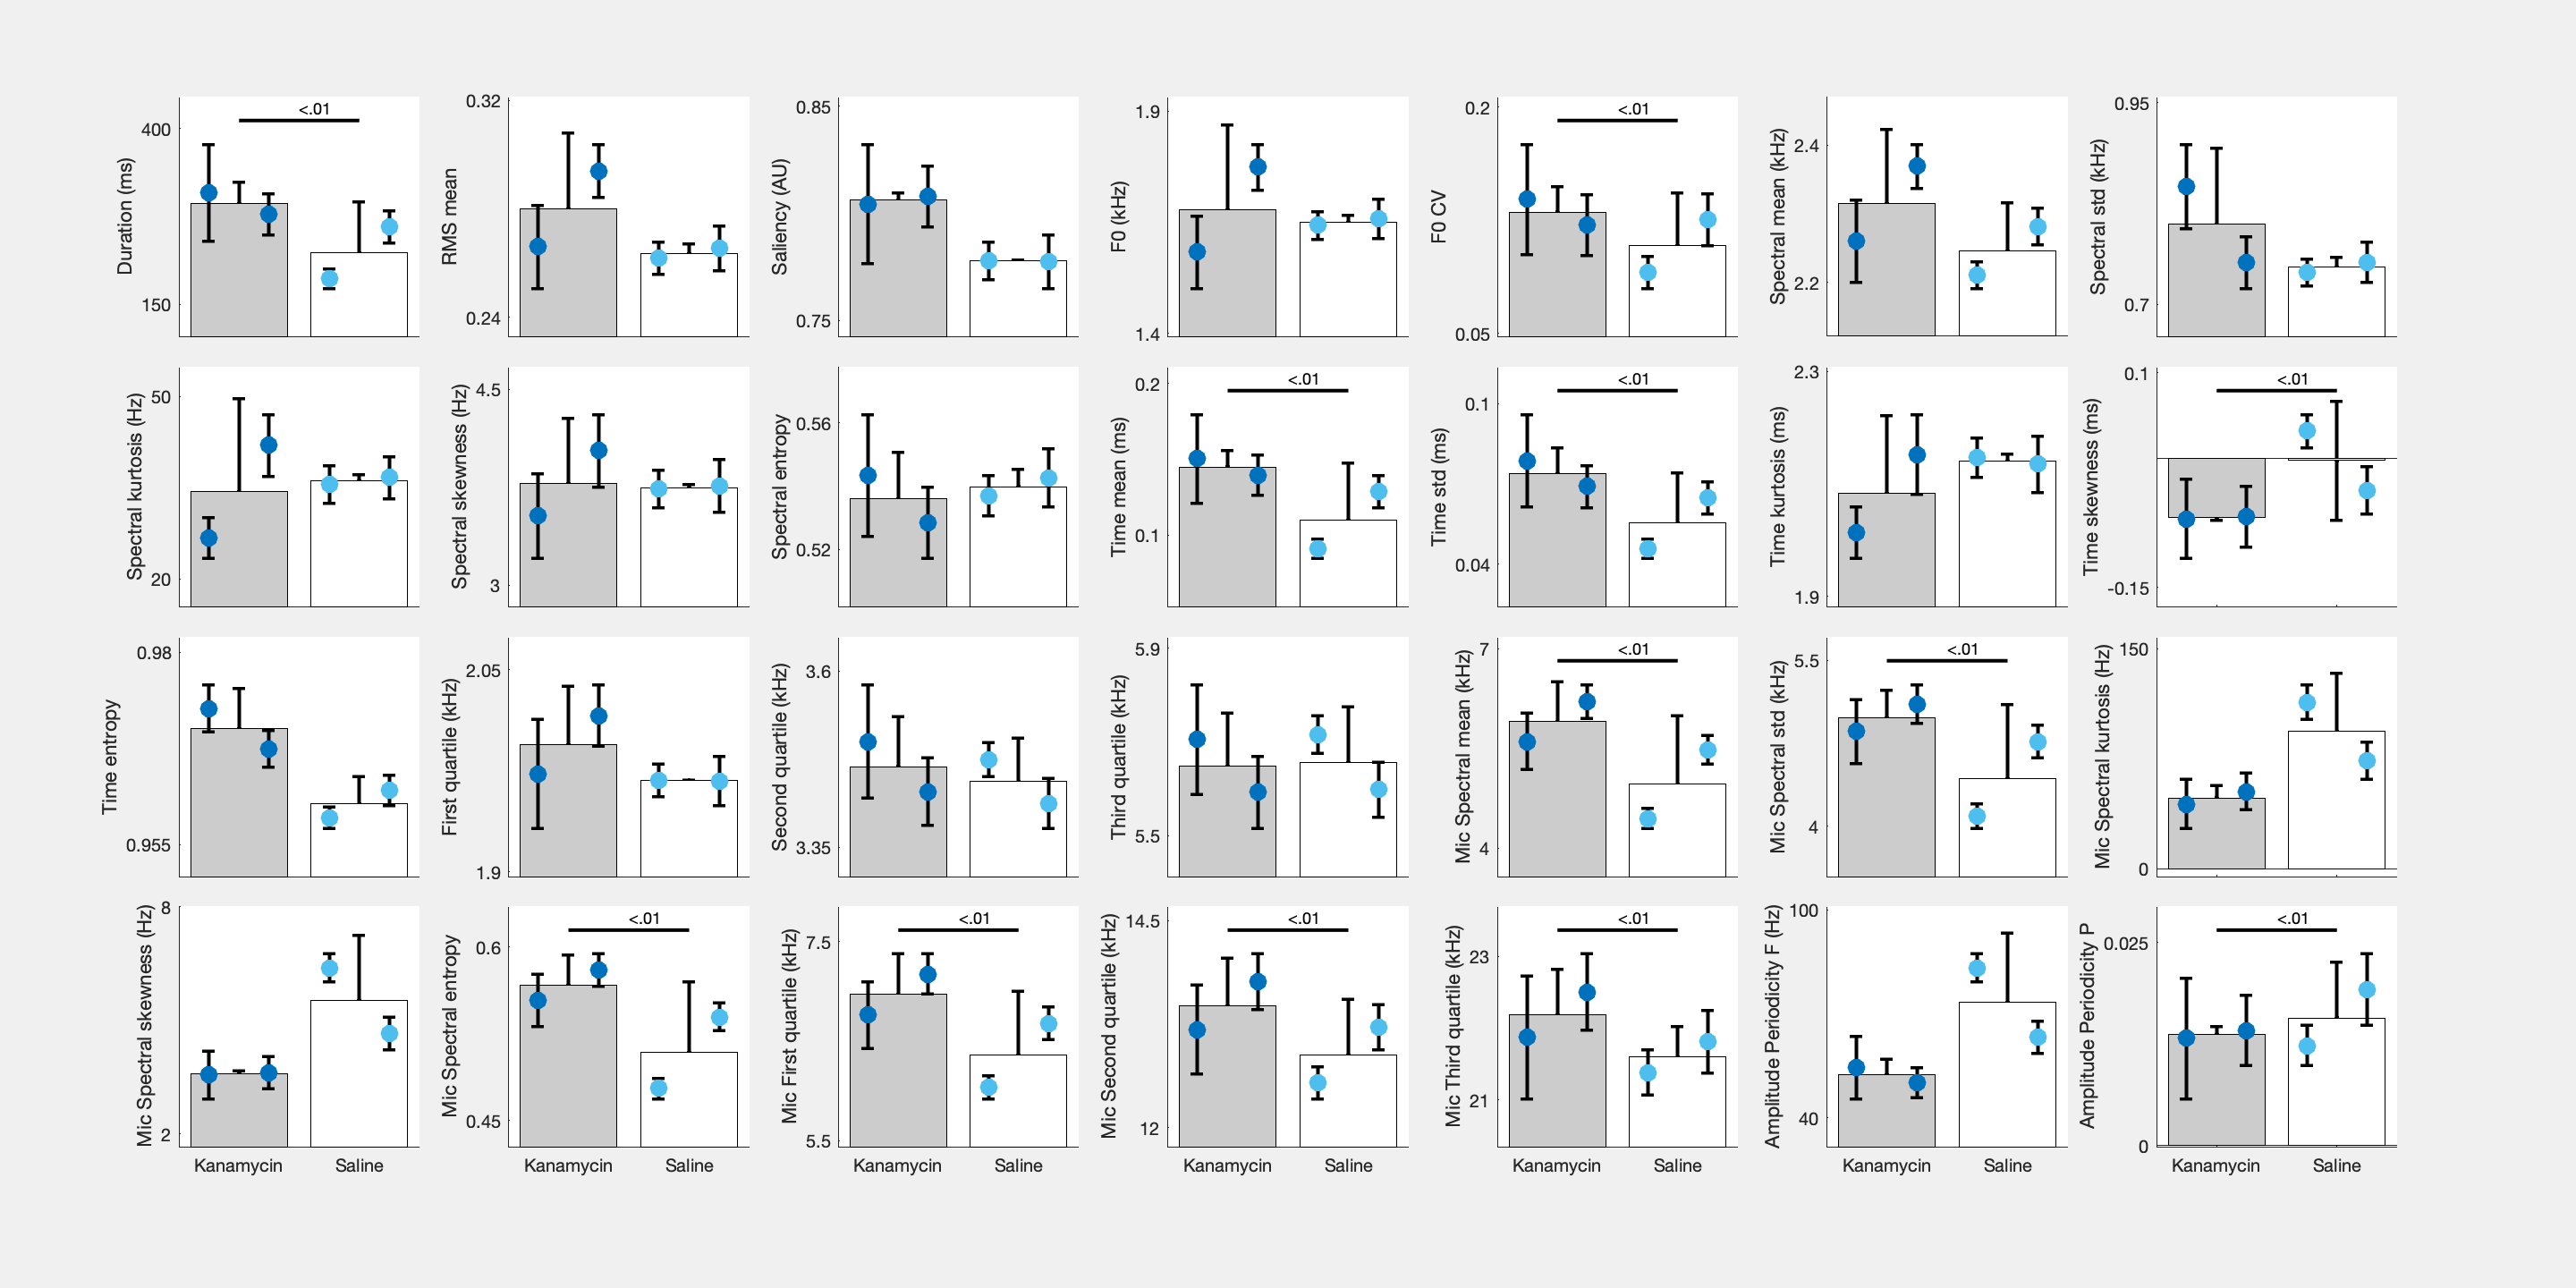

Fig1.Units = 'inches';
Fig1.Position(3:4) = [20 10];
Fig1.PaperSize = [20 10];

print(Fig1,fullfile(Path2Paper,'SupFigure14_PAF_MalesAcGroup5.pdf'),'-dpdf','-fillpage')

**Now correct all comparisons for false discovery rate (True proba = p*(Num_comparisons-rank))**

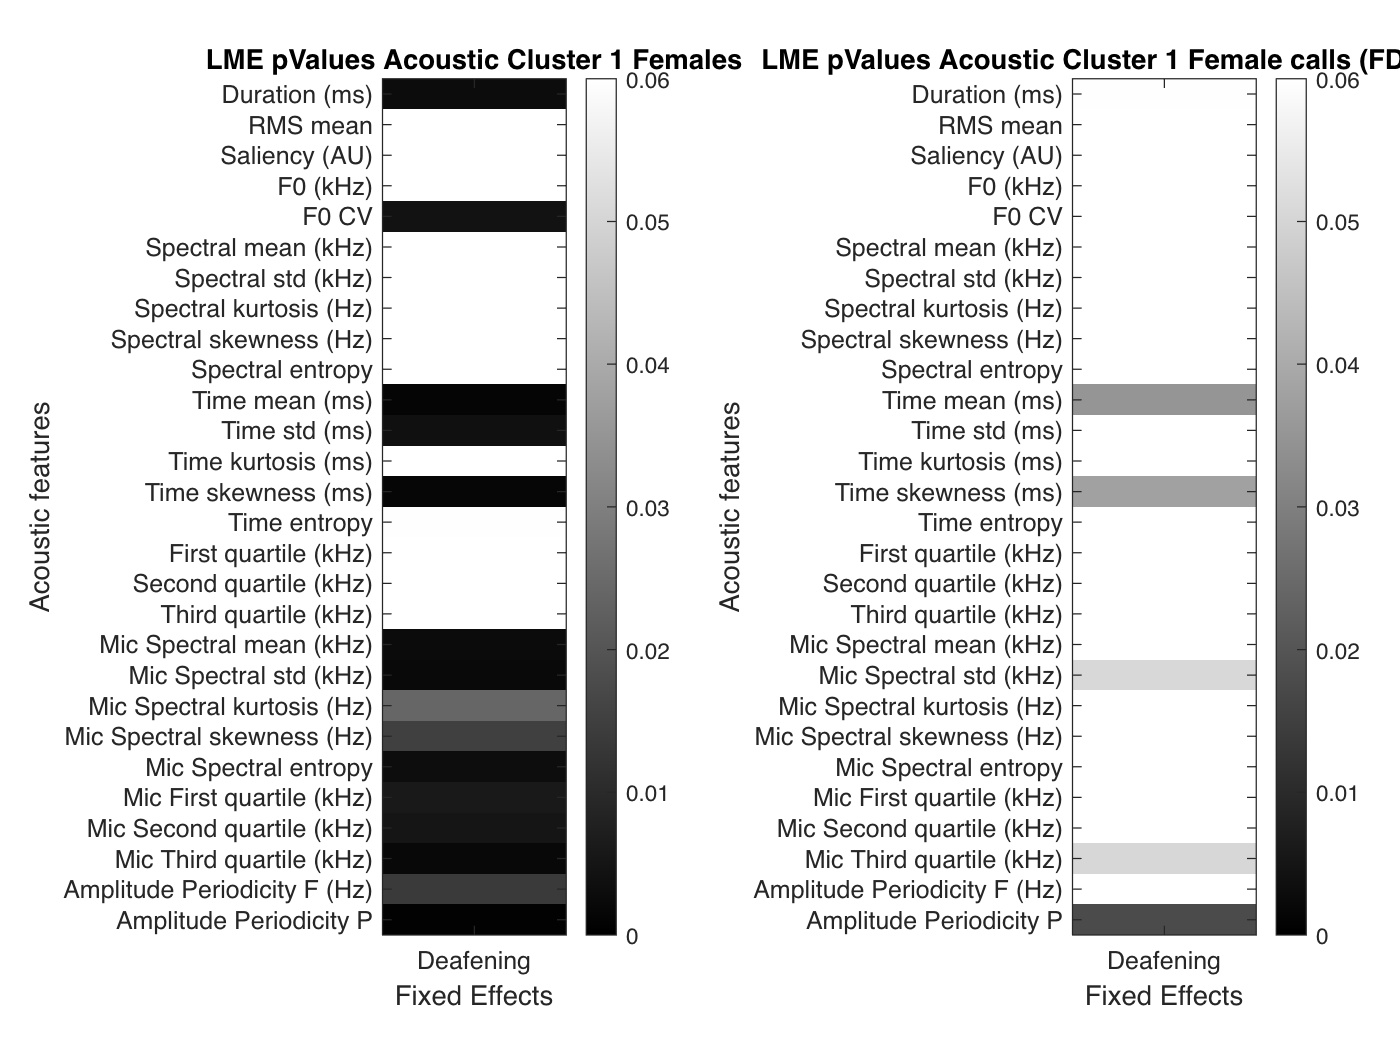

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank)) within each acoustic cluster
NVars = size(Pvalue_matrix_Post_hoc,1);

Pvalue_vector = Pvalue_matrix_Post_hoc;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_vectorFDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_vectorFDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
Pvalue_matrix_Post_hocFDR = Pvalue_vectorFDR;

figure()
tiledlayout(1,2)
nexttile
Im = imagesc(Pvalue_matrix_Post_hoc);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 5 Males')
nexttile
Im = imagesc(Pvalue_matrix_Post_hocFDR);
colorbar()
colormap(Im.Parent,'gray')
Im.Parent.CLim = [0 0.06];
set(gca, 'YTick', 1:(length(AcVars)), 'YTickLabel', AcVars)
set(gca, 'XTick', 1,'XTickLabel', {'Deafening'})
ylabel('Acoustic features')
xlabel('Fixed Effects')
title('LME pValues Acoustic Cluster 5 Male calls (FDR corrected)')

Pvalue_matrix_Post_hoc

Pvalue_matrix_Post_hoc =     0.0028
    0.6591
    1.0000
    0.7304
    0.0043
    0.7527
    0.5264
    1.0000
    1.0000
    1.0000


Pvalue_matrix_Post_hocFDR

Pvalue_matrix_Post_hocFDR =     0.0597
    4.6134
    3.0000
    4.3824
    0.0767
    3.7635
    4.2110
    2.0000
    1.0000
    1.0000
